Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" ([https://www.crcpress.com/9781138589940](https://www.crcpress.com/9781138589940))

# Quadrupole (Section 4.3.3)

Volker Ziemann, 211110, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

In this example we analyze a quadrupole magnet. We immediately realize, that it has a four-fold symmetry, such that we can restrict the simulation volume to one quadrant and later specify von-Neumann boundary conditions on the symmetry planes. 

Let's start with the definition of the iron yoke, which has a more complicated geometry thatn the dipoles we considered previously. In particular, the pole-face that has a hyperbolic shape; we approximate it by five straight segments. 

clear all; close all
yoke=[2;16; ...
  0; 0.25;0.3;0.3;0.2;0.2;0.15;0.07;0.06;0.05;0.04;0.03;0.02;0.10;0.10;0;
  0.3;0.3;0.25;0;0;0.1;0.1;0.02;0.0233;0.028;0.035;0.0467;0.07;0.15;0.2;0.2];

Also the coils have a more complicated shape. They are deifned as a five-sided polygon. Note that we define the enclosing volumen, the World, as five-sided polygon, with the origin expluded. Excluding the origin is necessary, because the there the von-Neumann boundary conditions (normal derivatives to the surface)  of the left-hand and the bottom boundary would clash.

C1=[2;5;0.1;0.2;0.2;0.15;0.1;0;0;0.1;0.1;0.05;zeros(22,1)];
C2=[2;5;0;0.1;0.1;0.05;0;0.2;0.2;0.15;0.1;0.1;zeros(22,1)]; 
World=[2;5;  0.001;0.4;0.4;0;0;  0;0;0.4;0.4;0.001;  zeros(22,1)];

Now we can define geometry `g`, create the `model` with one degree of freedom `u =` $A_z$, include the geometry in the model with geometryFromEdges(), and plot it.

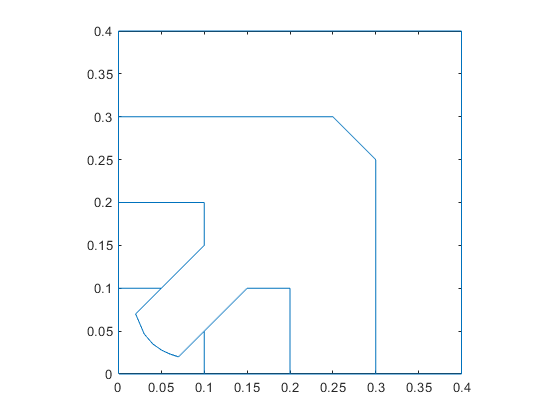

gd=[World,yoke,C1,C2];  % assemble geometry
ns=char('World','yoke','C1','C2')';  % names of the regions                 
sf='World+yoke+C1+C2'; 
g=decsg(gd,sf,ns);
model=createpde(1);
geometryFromEdges(model,g);
pdegplot(model)

After plotting the geometry once again, this time with `EdgeLabels` displayed, we can use this information to  specify boundary conditions. We set the potential `u = `$A_z$ on the boundaries `E1, E2,` and` E3` (the small edge at the origin)  of the `World` to zero. On the left-hand boundaries E26 to E29 and the bottom E12 to E15 we apply von-Neumann conditions, which will cause the model to obey the symmetries of the full magnet.

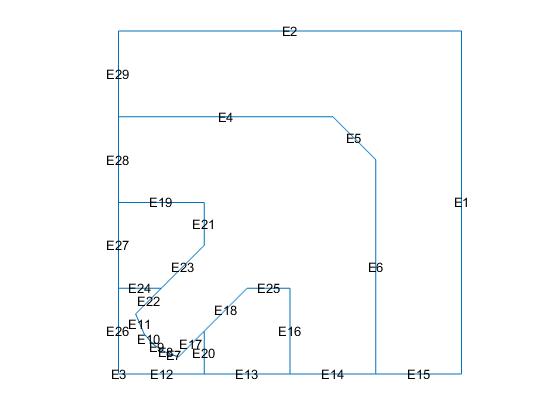

figure
pdegplot(model,'EdgeLabels','on'); axis off; axis equal

applyBoundaryCondition(model,'Edge',[1:3],'u',0);
applyBoundaryCondition(model,'Edge',[12:15,26:29],'q',0,'g',0);

In the next step we plot the model with SubDomainLabels shown and use that information to specify the material properties. The current density used is $J_z=10^6$ A/m^2 and $\mu_r =5000$.

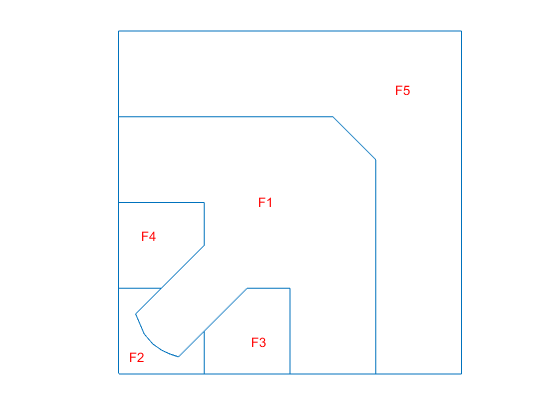

figure; pdegplot(model,'SubDomainLabels','on'); axis off; axis equal

specifyCoefficients(model,'m',0,'d',0,'c',1/5000,'a',0,'f',0,'Face',1);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0,'Face',[2,5]);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',-1.2566,'Face',3);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',1.2566,'Face',4);

Now we generate the mesh with a small mesh size of 5 mm and display it before solving the model and plotting u, which is available as the `NodalSolution` in the structure `result`.

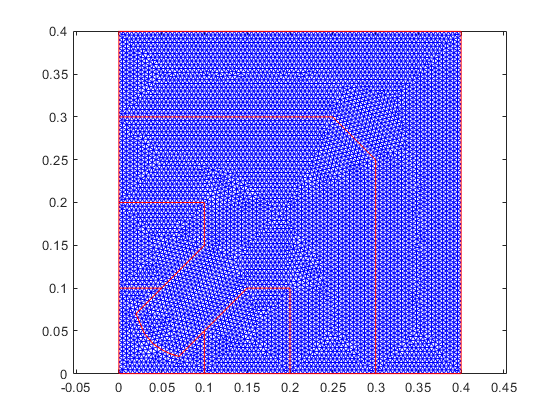

generateMesh(model,'Hmax',0.005);
figure; 
pdemesh(model);

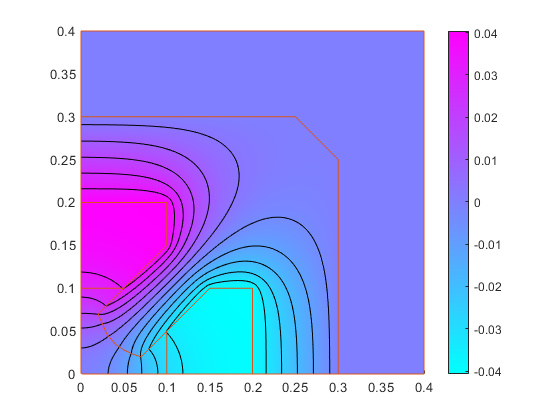

result=solvepde(model);
figure; 
pdeplot(model,'xydata',result.NodalSolution,'contour','on'); 
hold on; pdegplot(model)

As before we calculate the extract the magnitude of the magnetic field `Bn` and display it with the model superimposed. We find that the maximum field in this case is 1.4 T, which is below 2 T, the typical saturation level of iron.

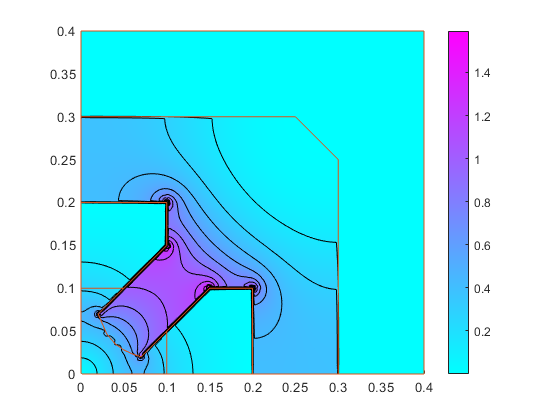

Bn=hypot(result.XGradients,result.YGradients);
figure; 
pdeplot(model,'xydata',Bn,'contour','on'); 
hold on; pdegplot(model); 

Since the beam dynamics depends on the gradient of a quadrupole, we determine it by evaluating Bn along a line on the diagonal from the origin (actually slightly off, because we had omitted the origin from the calculation volume) to close to the pole face. We find a nicely linear dependence.

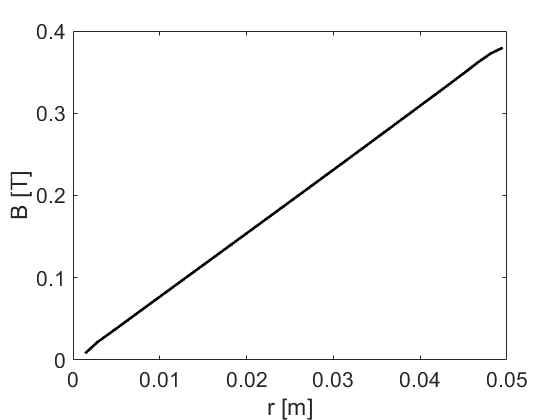

x=0.001:0.001:0.035; y=x;  % Diagonal
[By,Bx]=evaluateGradient(result,x,y);  Bx=-Bx;
B=hypot(Bx,By);
figure; plot(hypot(x,y),B,'k','LineWidth',2)
xlabel('r [m]'); ylabel('B [T]');
set(gca,'FontSize',16)

dlmwrite('Qmag2.dat',[x',B],'delimiter','\t');

Normally the gradient is specified as $\partial B_y/\partial x$ along the horizontal axis, but we leave this as a exercise.